## 数据读入

load RawData.mat
load svp.mat
load vessel.mat

HL=zeros(height(RawData),2);

disp("显示RawData每一行格式：");

显示RawData每一行格式：


disp(RawData(1,:));

    pingnum    beamnum     GNSS_Nm       GNSS_Em      GNSS_Zm    roll    pitch    heavem    heading    azimuth    angel     trans_times
    _______    _______    __________    __________    _______    ____    _____    ______    _______    _______    ______    ___________
       0          0       1.8082e+06    1.6224e+07    63.083     0.21    0.07       0        97.98     269.74     48.748      11.863   



%总beam数
N_beam=height(RawData);
%总ping数
N_ping=table2array(RawData(N_beam,1));%注意从零开始算
svp=table2array(svp);
RawData=table2array(RawData);
RawData(:,11)=RawData(:,11)./180.*pi;

% 计算所有的snell常数
p=sin(RawData(:,11))/svp(1,2);


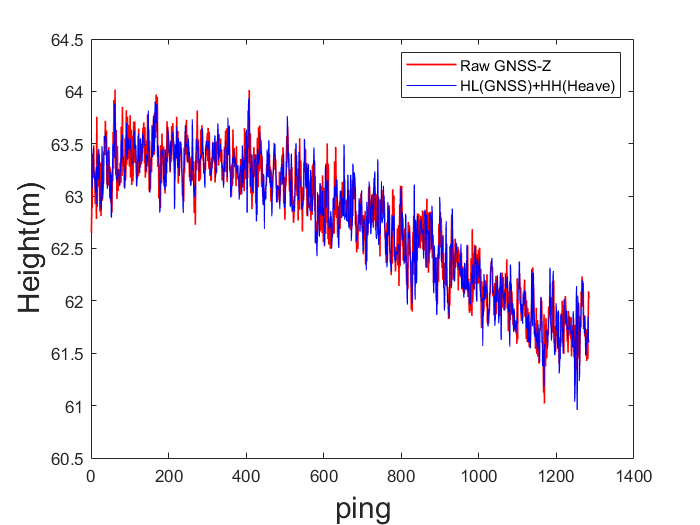

H_L=(RawData(1:432:N_beam,5));
time=1:1:N_ping+1;
figure
interval = [0 0.1];
tsoutnotch_HL = idealfilter(timeseries(H_L),interval,'pass');
tsoutnotchmean = tsoutnotch_HL;


H_H=RawData(1:432:N_beam,8);
HHmean = mean(H_H);
interval = [0 0.3];
tsoutnotch_HH = idealfilter(timeseries(H_H),interval,'notch');

temp=tsoutnotch_HL.Data+tsoutnotch_HH.Data+mean(H_L);
plot(time,temp,'r-',"LineWidth",1)
hold on
plot(time,H_L,'b-',"LineWidth",0.5)
legend('Raw GNSS-Z', 'HL(GNSS)+HH(Heave)')
xlabel('ping',"FontSize",18)
ylabel('Height(m)',"FontSize",18)

for i=1:1:N_beam/432
    if i==1 || i==2 || i==N_beam/432-1 || i==N_beam/432
        continue
    end
    
    RawData((i-1)*432+1:(i-1)*432+432,5)=ones(432,1).*temp(i);
end

## 声线跟踪

for i=1:1:N_beam
    
    t=RawData(i,12)/2;
    %用时
    num=1;
    L=0;
    H=0;
    
    while t>0
%         if num+1>length(svp(:,1))
%             c_0=svp(num,2);
%             s_i=c_0*t;
%             H=H+s_i*sqrt(1-p(i)^2*c_0^2);
%             L=L+s_i*p(i)*c_0;
%             break
%         else
            c_1=svp(num+1,2);
            c_0=svp(num,2);
            h=svp(num+1,1)-svp(num,1);
            g=(c_1-c_0)/h;
            
            cos_i0=sqrt(1-p(i)^2*c_0^2);
            cos_i1=sqrt(1-p(i)^2*c_1^2);
            
            if g==0 %常声速
                L_i=h*p(i)*c_0/cos_i0;
                d_t=h/cos_i0/c_0;
            else %常梯度
                L_i=(cos_i0-cos_i1)/p(i)/g;
                d_t=(asin(p(i)*c_1)-asin(p(i)*c_0))/(p(i)*g^2*h)*log(1+g*h/c_0);
            end
            
            if t>d_t
                t=t-d_t;
                L=L+L_i;
                H=H+h;
                num=num+1;
            else
                c_t=exp(t*g)*c_0;
                H=H+(c_t-c_0)/g;
                L=L+h*tan(asin(p(i)*c_0));
                break
            end
        end
        
%     end
    HL(i,:)=[H,L];
end

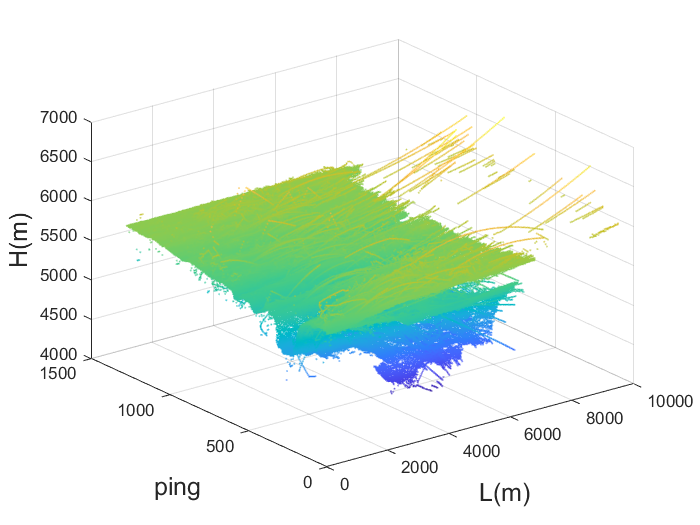

figure
scatter3(HL(1:N_beam,2),RawData(1:N_beam,1),HL(1:N_beam,1),5,HL(1:N_beam,1),'.')
ylabel('ping',"FontSize",15)
xlabel('L(m)',"FontSize",15)
zlabel('H(m)',"FontSize",15)

## 坐标归算

% 换能器相对于GNSS 在船体坐标系VFS下的向量
VFS_T0_G0=(vessel(:,2)-vessel(:,3))';

roll=RawData(:,6)./180*pi; % 横摇
pitch=RawData(:,7)./180*pi; % 纵摇
heading=RawData(:,9)/180*pi; % 船首在地理坐标系下航向角
azimuth=RawData(:,10)/180*pi; % 波束相对于换能器方位角

% 换能器坐标系TFS下波束点坐标
TFS_P(:,1)=HL(:,2).*cos(azimuth); % x坐标
TFS_P(:,2)=HL(:,2).*sin(azimuth); % y坐标
TFS_P(:,3)=HL(:,1); % z坐标

% 对换能器-GNSS向量做姿态改正
VFS_T_G=zeros(N_beam,3);
for i=1:N_beam
    R_r=[1,0,0;...
        0,cos(roll(i)),sin(roll(i));...
        0,-sin(roll(i)),cos(roll(i))];
    R_p=[cos(pitch(i)),0,sin(pitch(i));...
        0,1,0;...
        -sin(pitch(i)),0,cos(pitch(i))];
    VFS_T_G(i,:)=(R_p*R_r*(VFS_T0_G0(1,:)'))';
end

% 波束点在船体坐标系VFS下相对于GNSS坐标
VFS_P_G=TFS_P+VFS_T_G;

% 波束点在地理坐标系GRF下的地理坐标
GRF_P=zeros(N_beam,3);
for i=1:N_beam
    R_A=[cos(heading(i)),-sin(heading(i)),0;...
        sin(heading(i)),cos(heading(i)),0;...
        0,0,1];
    GRF_P(i,:)=([RawData(i,3);RawData(i,4);RawData(i,5)]+R_A*[VFS_P_G(i,1);VFS_P_G(i,2);-VFS_P_G(i,3)])';
end

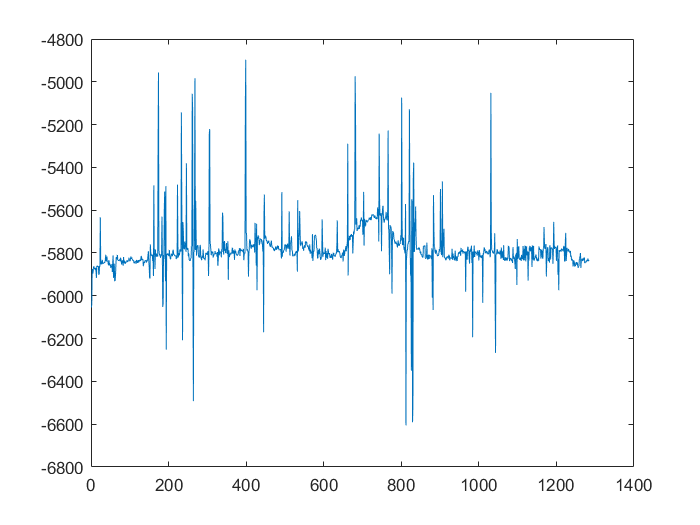

P_x=zeros(N_ping+1,432);
P_y=zeros(N_ping+1,432);
P_z=zeros(N_ping+1,432);
for i=1:1:N_beam/432
    P_x(i,:)=GRF_P((i-1)*432+1:(i-1)*432+432,1)';
    P_y(i,:)=GRF_P((i-1)*432+1:(i-1)*432+432,2)';
    P_z(i,:)=GRF_P((i-1)*432+1:(i-1)*432+432,3)';
end

figure
plot(P_z(:,1),'DisplayName','所有ping的第一beam波束点z坐标变化')

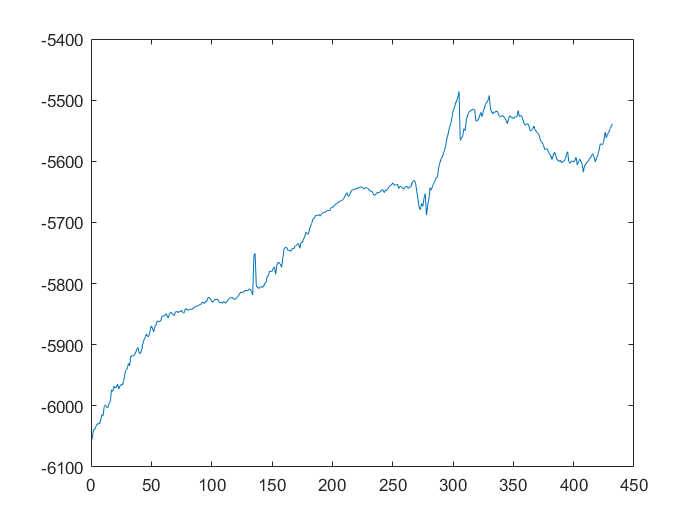


figure
plot(P_z(1,:),'DisplayName','第一ping的z坐标变化')

## 对深度值进行滤波

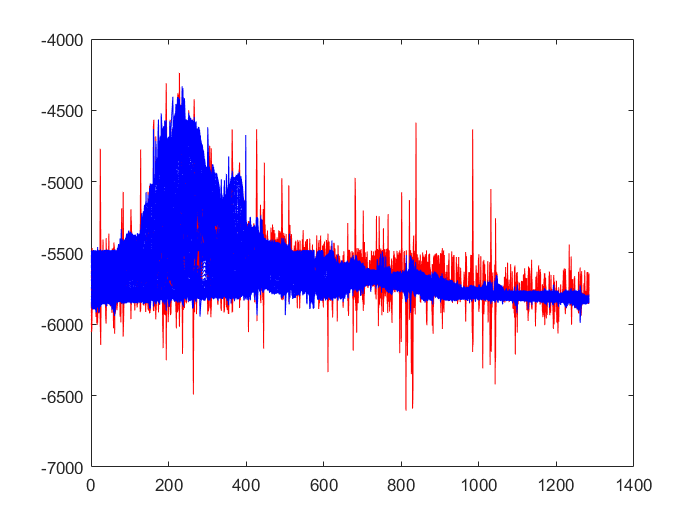

figure
plot(P_z,'r-')
hold on
temp2=P_z;
for i=1:1:432
    for j=1:20:1300
        if j+30>1284
            temp2(j:1284,i)=filloutliers(temp2(j:1284,i),"linear",'movmedian',40);
        else
            temp2(j:j+30,i)=filloutliers(temp2(j:j+30,i),"linear",'movmedian',40);      
        end
    end
    
end
plot(temp2,'b-')

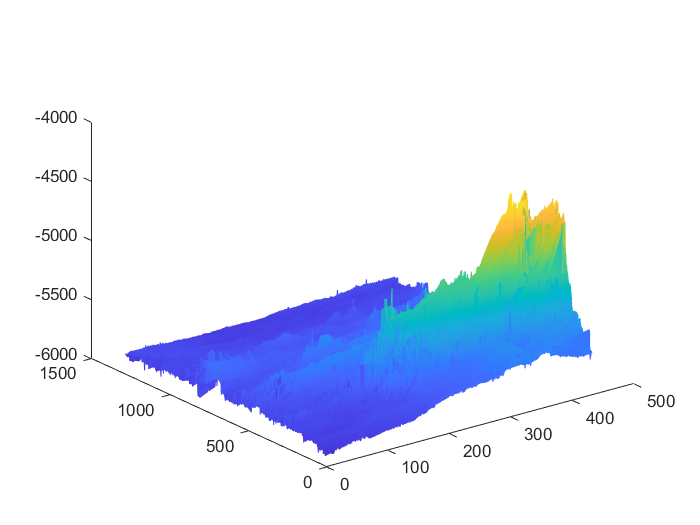

figure
mesh(temp2)
grid off

## 尝试理想滤波器

% figure
% plot(P_z(:,1),'r-')
% hold on
% plot(idealfilter(timeseries(P_z(:,1)),[0 0.1],'pass')+mean(P_z(:,1)),'b-')

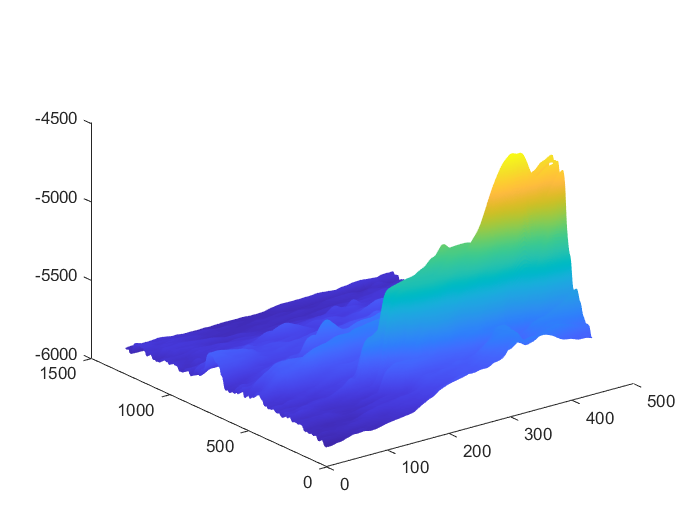

figure
Iblur1 = imgaussfilt(temp2,4);
mesh(Iblur1)
grid off

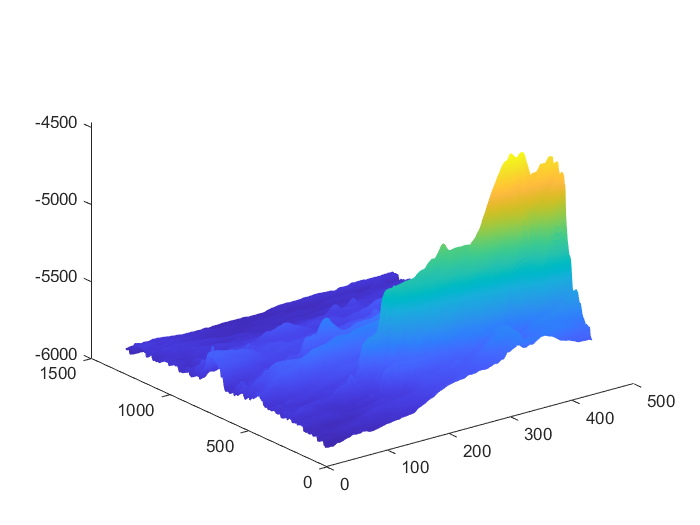

Igaussian = imgaussfilt(temp2,2);
figure
mesh(Igaussian)
grid off

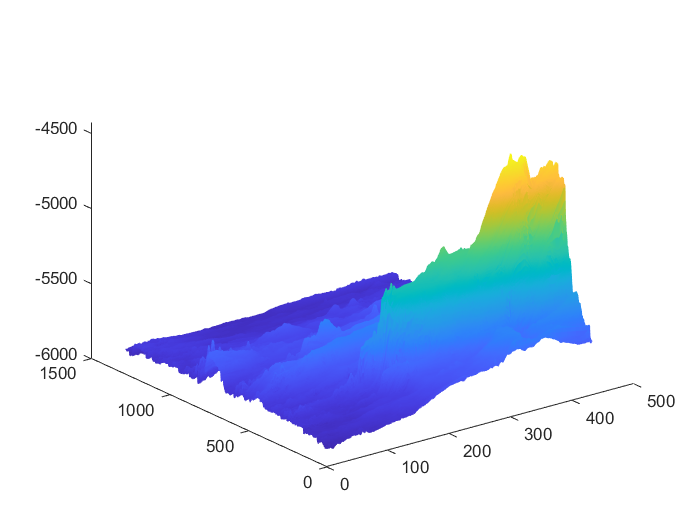

Igaussian2 = imgaussfilt(temp2,1);
figure
mesh(Igaussian2)
grid off

P_z=Igaussian2;

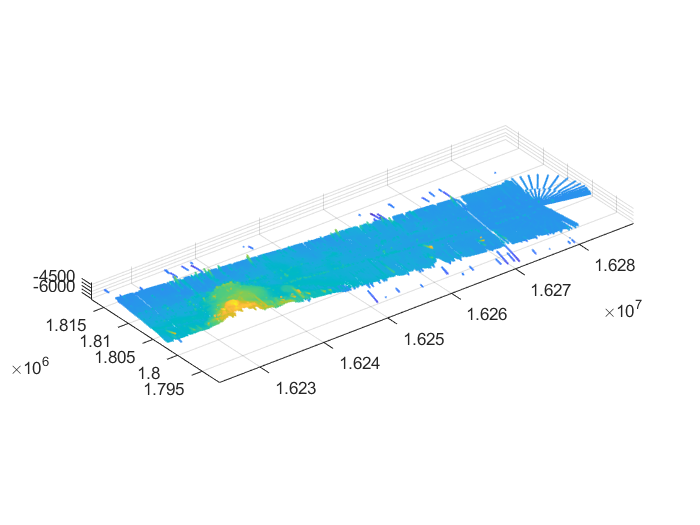

figure
scatter3(GRF_P(:,2),GRF_P(:,1),GRF_P(:,3),5,GRF_P(:,3),'.')
axis equal

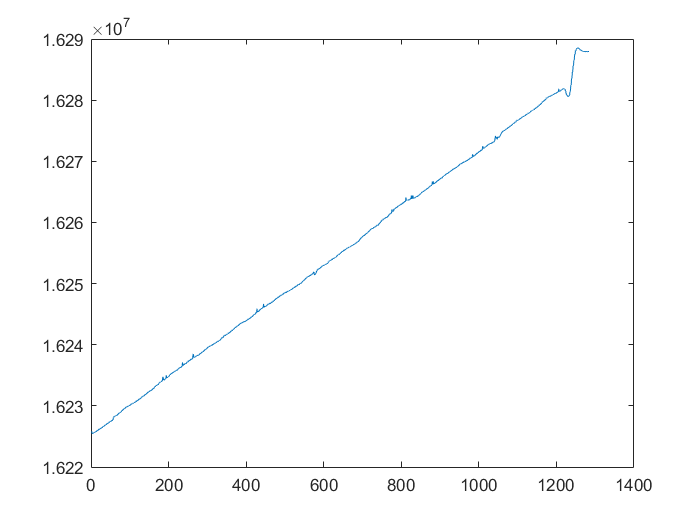

plot(P_y(:,1))

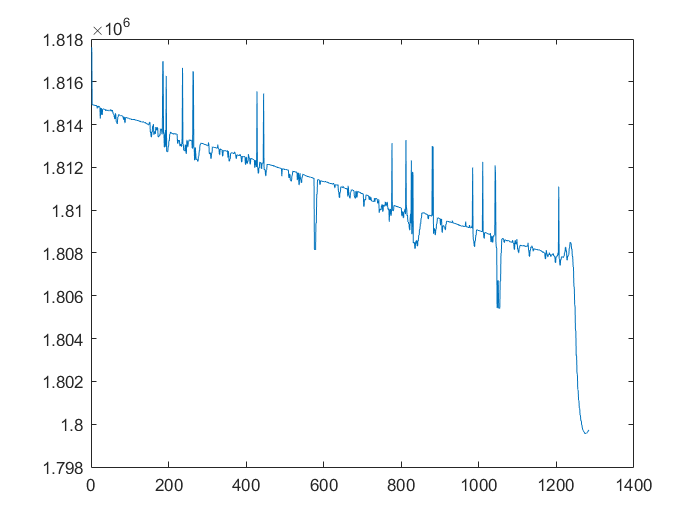

figure
plot(P_x(:,1))

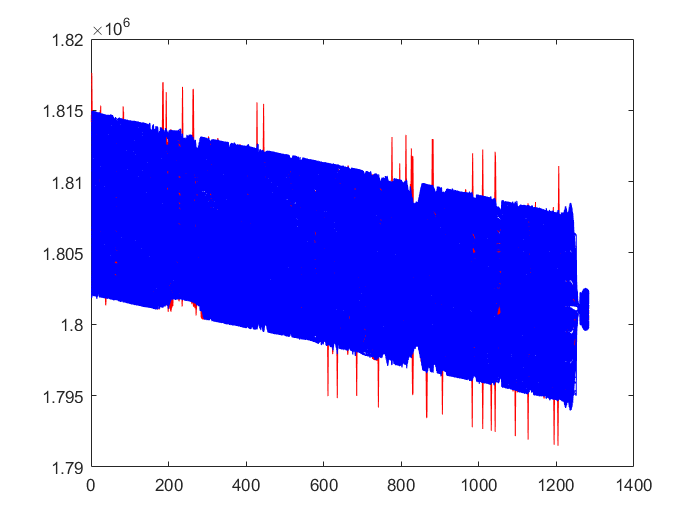

figure

plot(P_x,'r-')

hold on
temp3=P_x;
for i=1:1:432
    for j=1:20:1300
        if j+30>1284
            temp3(j:1284,i)=filloutliers(temp3(j:1284,i),"linear",'movmedian',40);
        else
            temp3(j:j+30,i)=filloutliers(temp3(j:j+30,i),"linear",'movmedian',40);
        end
    end
end

plot(temp3,'b-')

P_x=temp3;

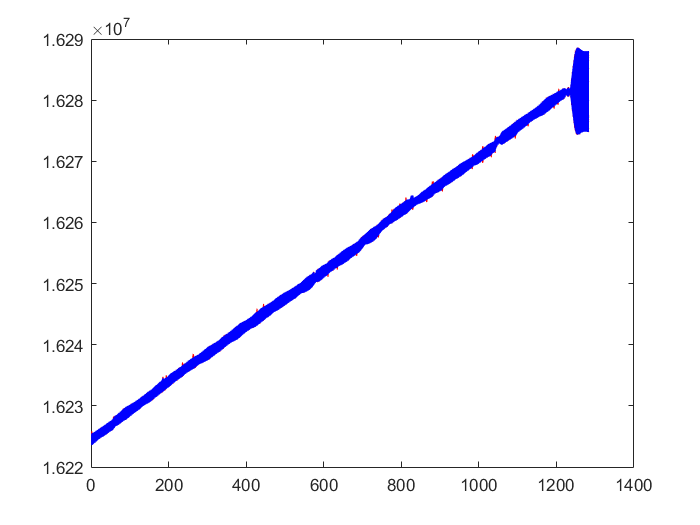

figure
plot(P_y,'r-')
hold on
temp4=P_y;
for i=1:1:432
    for j=1:20:1300
        if j+25>1284
            temp4(j:1284,i)=smoothdata(temp4(j:1284,i),"rlowess");
        else
            temp4(j:j+25,i)=smoothdata(temp4(j:j+25,i),"rlowess");
        end
    end
end

plot(temp4,'b-')

P_y=temp4;

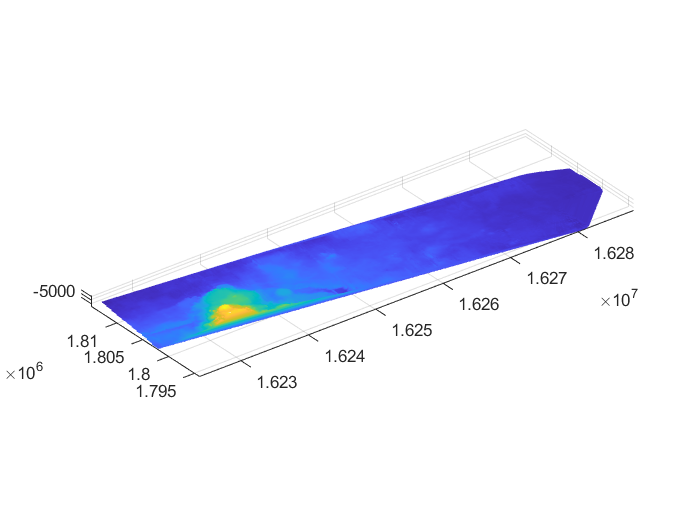

Xp1=zeros(N_beam,1);
Yp1=zeros(N_beam,1);
Zp1=zeros(N_beam,1);
for i=0:1:N_ping
    Xp1(i*432+1:i*432+432,1)=P_x(i+1,:)';
    Yp1(i*432+1:i*432+432,1)=P_y(i+1,:)';
    Zp1(i*432+1:i*432+432,1)=P_z(i+1,:)';
end
x=linspace(min(Xp1),max(Xp1),1200);
y=linspace(min(Yp1),max(Yp1),400);
[X,Y]=meshgrid(x,y);
Z=griddata(Xp1(~isnan(Xp1)),Yp1(~isnan(Xp1)),Zp1(~isnan(Xp1)),X,Y,"linear");
figure
surf(Y,X,Z,'EdgeColor',"interp",'FaceColor',"interp");
axis equal

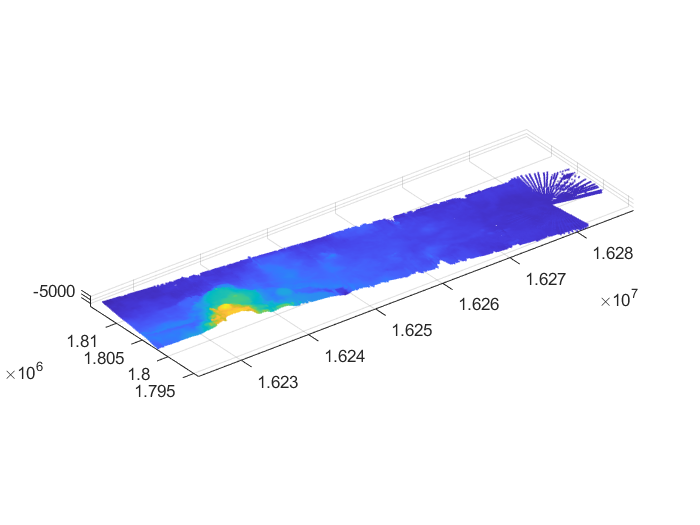

figure
scatter3(Yp1(~isnan(Xp1)),Xp1(~isnan(Xp1)),Zp1(~isnan(Xp1)),5,Zp1(~isnan(Xp1)),'.')
axis equal

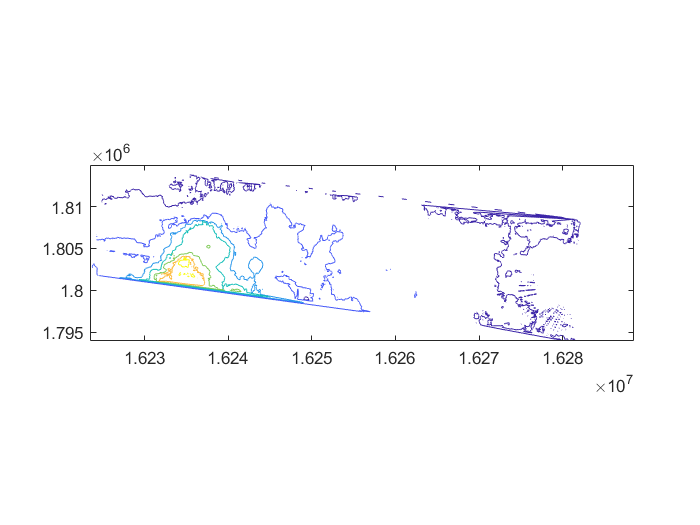

figure
contour(Y,X,Z)
axis equal

result1=[Xp1,Yp1,Zp1];
save ./result1.txt result1 -ascii -tabs
save ./result0.txt GRF_P -ascii -tabs

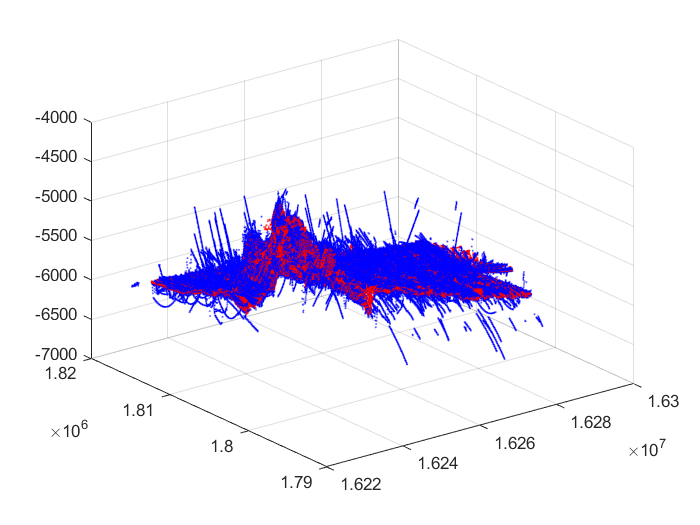

figure
scatter3(GRF_P(:,2),GRF_P(:,1),GRF_P(:,3),1,GRF_P(:,3),'b.')
hold on
scatter3(Yp1,Xp1,Zp1,1,GRF_P(:,3),'r.')

% axis equal

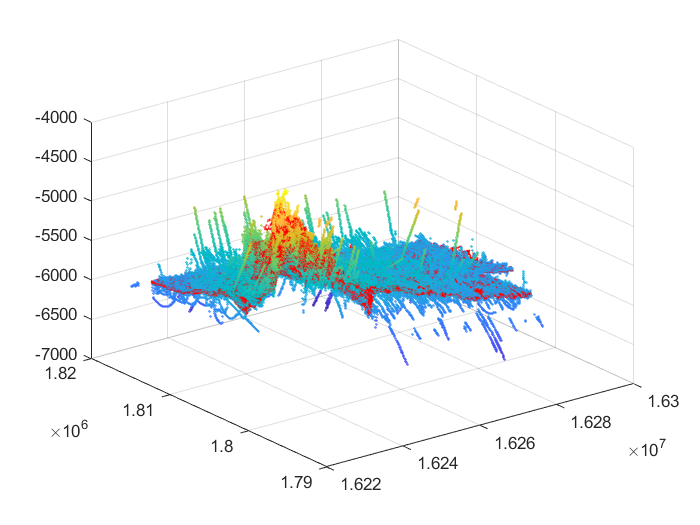

figure
scatter3(GRF_P(:,2),GRF_P(:,1),GRF_P(:,3),1,GRF_P(:,3))
hold on
scatter3(Yp1,Xp1,Zp1,0.5,GRF_P(:,3),'r.')

% axis equal